# **Численные методы в СПб АУ РАН**

## **Задание по практике №6**

Кузьмичев Артём, 4 курс

## **№5**

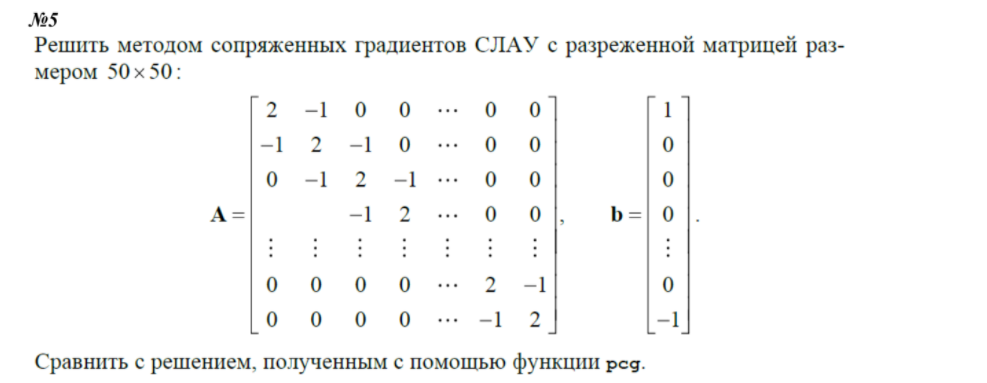

## Решение:

Инициализируем трёхдиагональную матрицу A из условия

N = 50;
e = ones(N,1);
A = spdiags([-e 2*e -e],-1:1,N,N);

Проверим, что получилось именно то, что и было нужно, осуществив вывод на экран разреженной матрицы (sparse array) в обычном виде (full-storage)

full(A) 

ans =      2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0 

Инициализируем $b={\left\lbrack \begin{array}{ccccc}
1 & 0 & \cdots  & 0 & -1
\end{array}\right\rbrack }^T$ как sparse array

b = sparse(N,1);
b(1) = 1;
b(end) = -1;

Параметры алгоритмов - погрешность и максимальное число итераций алгоритма

tol = 1e-7;
maxit = 20;

Решим систему  c помощью функции conjgrad (опредление в конце скрипта .mlx) 

X  = conjgrad(A,b,tol,maxit)

conjgrad остановил выполнение на итерации 20, так как достигнуто максимальное число итераций 
Относительная невязка 4.761905e-02

X =     0.9524
    0.9048
    0.8571
    0.8095
    0.7619
    0.7143
    0.6667
    0.6190
    0.5714
    0.5238


Решим систему  c помощью встроенной функции pcg c теми же параметрами

Xpcg = pcg(A,b,tol,maxit)

pcg stopped at iteration 20 without converging to the desired tolerance 1e-07
because the maximum number of iterations was reached.
The iterate returned (number 20) has relative residual 0.048.


Xpcg =     0.9524
    0.9048
    0.8571
    0.8095
    0.7619
    0.7143
    0.6667
    0.6190
    0.5714
    0.5238


Убедимся, что результат эквивалентен. Возможная пренебрежимо малая ненулевая разница между столбцами может быть вызвана машинной арифметики

max(Xpcg-X)

ans = 0

## Приложение

#### Определение функции, осуществляющей решение СЛАУ методом сопряженных градиентов

function X = conjgrad(A, b, tol, maxit) 
%Вход   -   A   - симметричная положительно определённая матрица N x N
%       -   b   - столбец N x 1 - правая часть СЛАУ
%       -   tol - значение невязки, при котором итерации останавливаются
%       -   maxit - максимальное число итераций
%Выход  -   X   - столбец решения СЛАУ

% начальное приближение
X = zeros(size(b));
r = b - A*X;
p = r; 
rsold = r' * r; 

for i=1:maxit
    Ap = A * p;
    alpha = rsold / (p' * Ap); 
    X = X + alpha * p; 
    r = r - alpha * Ap; 
    rsnew = r' * r; 
    rrel = sqrt(rsnew)/norm(b);
    if rrel < tol
        fprintf('conjgrad сошёлся на итерации %i с относительной невязкой %e',i,rrel)
        break;
    end 
    p = r + (rsnew / rsold) * p; 
    rsold = rsnew;
end

if i == maxit
    fprintf('conjgrad остановил выполнение на итерации %i, так как достигнуто максимальное число итераций \nОтносительная невязка %e',i, rrel)
end 

end